# Shiting Poles of a lowly damped PT2 System

# Gezielte Polverschiebung für schwach gedämpftes PT2 System

clear
s = tf('s');
w0 = 4; D= 0.2; K = 0.25

K = 0.2500

G = K*w0^2/(s^2 + 2*D*w0*s + w0^2)


G =
 
         4
  ----------------
  s^2 + 1.6 s + 16
 
Continuous-time transfer function.



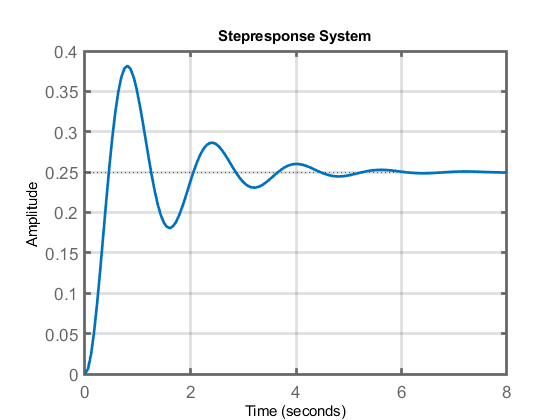

step(G); grid on;
h=gca; h.LineWidth = 2; h.FontSize =13; h.Children(1).Children(2).LineWidth =2;
title('Stepresponse System')

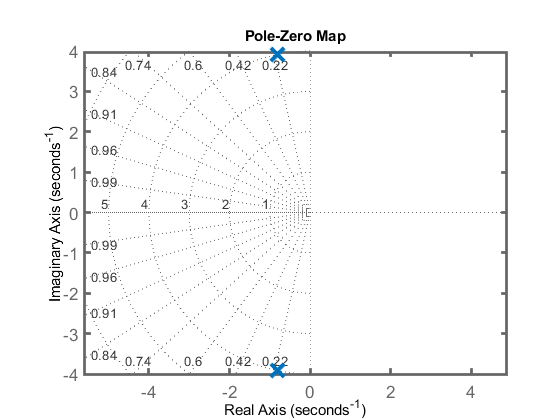

% Pole Zero Map
figure(2); pzmap(G); axis equal; grid
h=gca; h.LineWidth = 2; h.FontSize =13;
h.Children(1).Children(2).MarkerSize =14;
h.Children(1).Children(2).LineWidth =3;

## P-Controller

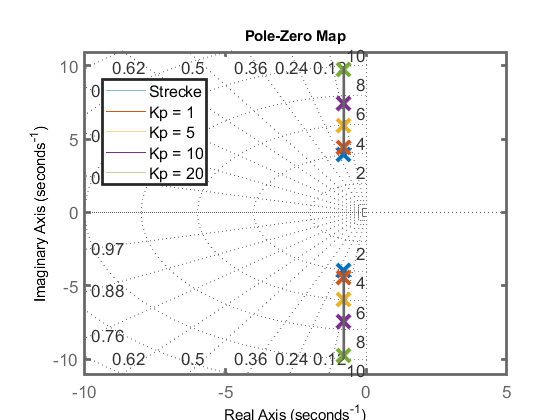

Kp = [1 5 10 20];

leg{1} = 'Strecke';
for i=1:length(Kp)
    T = minreal(Kp(i)*G/(1+Kp(i)*G));
    figure(2); hold on; pzmap(T)
    h.Children(1).Children(2).MarkerSize =14; h.Children(1).Children(2).LineWidth =3;
    leg{i+1} = ['Kp = ',num2str(Kp(i))];
end

rl = rlocus(G,[0.01,Kp(end)+1]);
plot(real(rl(1,:)), imag(rl(1,:))); h.Children(1).LineWidth = 2; h.Children(1).Color = [0.4,0.4,0.4];
plot(real(rl(2,:)), imag(rl(2,:))); h.Children(1).LineWidth = 2; h.Children(1).Color = [0.4,0.4,0.4];
hleg=legend([leg,'','']); hleg.Location = 'best';
h=gca; h.LineWidth = 2; h.FontSize =13;
h.XLim = [-10 5]; h.YLim = [-11 11];

## PDT1-Controller

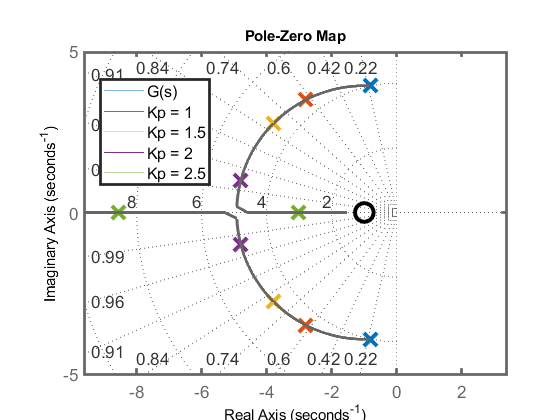

clear leg
figure(3); pzmap(G); axis equal; grid on
h=gca; h.LineWidth = 2; h.FontSize =13;
leg{1} = 'G(s)';
h.Children(1).Children(2).MarkerSize =14;
h.Children(1).Children(2).LineWidth =3;
Kp = [1 1.5 2 2.5];

for i=1:length(Kp)
    
    R = Kp(i)*(s+1);
    
    T = minreal(R*G/(1+R*G));
    figure(3); hold on; pzmap(T)
    
    % Visuals
    h.Children(1).Children(2).MarkerSize =14; h.Children(1).Children(2).LineWidth =3;
    h.Children(1).Children(1).MarkerSize =14; h.Children(1).Children(1).LineWidth =3;
    h.Children(1).Children(1).Color = 'black';
    leg{i+1} = ['Kp = ',num2str(Kp(i))];
end


% Visuals
h.XLim(1) = h.XLim(1)-4; h.XLim(2) = h.XLim(2)-1.5;
h.YLim(1) = h.YLim(1)-1; h.YLim(2) = h.YLim(2)+1;

rl = rlocus(minreal(G*(s+1)),[0.01:0.01:Kp(end)+5]);
plot(real(rl(1,:)), imag(rl(1,:))); h.Children(1).LineWidth = 2; h.Children(1).Color = [0.4,0.4,0.4];
plot(real(rl(2,:)), imag(rl(2,:))); h.Children(1).LineWidth = 2; h.Children(1).Color = [0.4,0.4,0.4];
hleg=legend([leg,'','']); hleg.Location = 'best';

## PIDT1-Controller

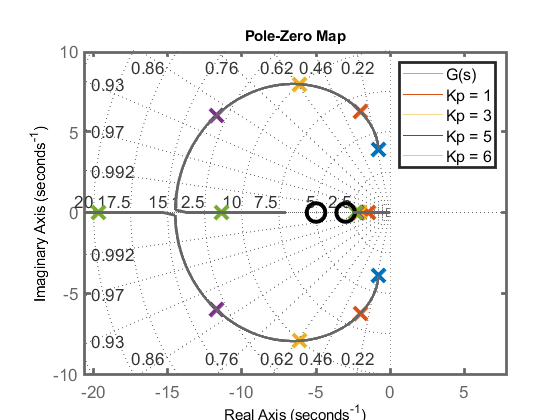

clear leg
figure(4); pzmap(G); axis equal; grid on
h=gca; h.LineWidth = 2; h.FontSize =13;
leg{1} = 'G(s)';
h.Children(1).Children(2).MarkerSize =14;
h.Children(1).Children(2).LineWidth =3;
Kp = [1 3 5 6];

for i=1:length(Kp)
    
    R = Kp(i)*(s+5)*(s+3)/s/(0.01*s +1);
    
    T = minreal(R*G/(1+R*G));
    figure(4); hold on; pzmap(T)
    h.Children(1).Children(2).MarkerSize =14; h.Children(1).Children(2).LineWidth =3;
    h.Children(1).Children(1).MarkerSize =14; h.Children(1).Children(1).LineWidth =3;
    h.Children(1).Children(1).Color = 'black';
    leg{i+1} = ['Kp = ',num2str(Kp(i))];
end

h.XLim(1) = h.XLim(1)-15; h.XLim(2) = h.XLim(2)+3;
h.YLim(1) = h.YLim(1)-2; h.YLim(2) = h.YLim(2)+2;

rl = rlocus(minreal(G*(s+5)*(s+3)/s/(0.01*s +1)),[0.01:0.01:Kp(end)+5]);
plot(real(rl(1,:)), imag(rl(1,:))); h.Children(1).LineWidth = 2; h.Children(1).Color = [0.4,0.4,0.4];
plot(real(rl(2,:)), imag(rl(2,:))); h.Children(1).LineWidth = 2; h.Children(1).Color = [0.4,0.4,0.4];
plot(real(rl(3,:)), imag(rl(3,:))); h.Children(1).LineWidth = 2; h.Children(1).Color = [0.4,0.4,0.4];
plot(real(rl(4,:)), imag(rl(4,:))); h.Children(1).LineWidth = 2; h.Children(1).Color = [0.4,0.4,0.4];
hleg=legend([leg,'','']);

## Disturbance resonse to a steo with Kp= 5 (results in a Damoing of 0.9 for dominating pole pair, however, overshoor due to zeros!)

## Stör- und Sprungantwort für Kp = 5 (ergibt D~0.9 des dominierendes Polpaars (aber mehr Überschwingen in T durch Nullstellen!))

Kp = 5; % Control gain
R = Kp*(s+3)*(s+5)/s/(0.01*s +1); % Controller
L = minreal(G*R); % Open loop
zpk(minreal(L/(1+L))); %Closed loop

% Visuals
figure(5)
step(L/(1+L),G/(1+L),4); grid on; hold on

% Poles
damp(minreal(L/(1+L)))

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -2.28e+00                 1.00e+00       2.28e+00         4.38e-01    
 -1.17e+01 + 6.03e+00i     8.89e-01       1.32e+01         8.55e-02    
 -1.17e+01 - 6.03e+00i     8.89e-01       1.32e+01         8.55e-02    
 -7.59e+01                 1.00e+00       7.59e+01         1.32e-02    


% Use a feedforward filter to compensate zero (see chapter 4_IV)
% Mit und ohne Vorsteuerung (s. vorlesungs Kaptiel 4_IV)
zi = zero(minreal(L/(1+L)))

zi =    -5.0000
   -3.0000


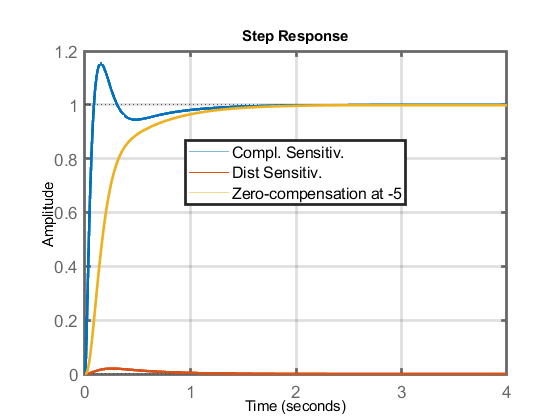

step(minreal(L/(1+L))/(1/(-zi(1))*s+1))
%step(minreal(L/(1+L))/(1/(-zi(2))*s+1))
%step(minreal(L/(1+L))/(1/(-zi(2))*s+1)/(1/(-zi(1))*s+1))

% Visuals
h=gca; h.LineWidth = 2; h.FontSize =13;
h.Children(1).Children(2).LineWidth =2;
h.Children(2).Children(2).LineWidth =2;
try
h.Children(3).Children(2).LineWidth =2;
%h.Children(4).Children(2).LineWidth =2;
%h.Children(5).Children(2).LineWidth =2;
%hleg = legend('Führungsübertragung','Störübertragung',['NS Kompensation bei ',num2str(zi(1))],['NS Kompensation bei ',num2str(zi(2))],['NS Kompensation bei ',num2str(zi(1)),' & ',num2str(zi(2))]);
hleg = legend('Compl. Sensitiv.','Dist Sensitiv.',['Zero-compensation at ',num2str(zi(1))]);

hleg.Location = 'best';
catch
hleg = legend('Führungsübertragung','Störübertragung');hleg.Location = 'best';
end

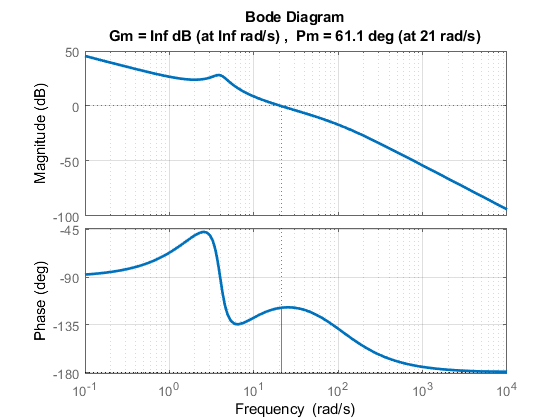

% Bode plot (for later)
figure(6);
margin(L); grid on;
h=gcf;
lines = findobj(h.Children(2),'Type','Line'); set(lines,'Linewidth',2);
lines = findobj(h.Children(3),'Type','Line'); set(lines,'Linewidth',2);

## Comparison between PZ compensation and Root Locus design approach

## Vergleich zur Auslegung mittels reiner PN Kompensation 

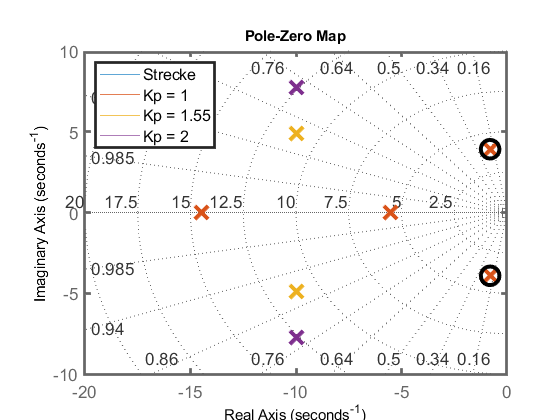

%Visuals
clear leg
figure(7); pzmap(G); axis equal; grid on;
h=gca; h.LineWidth = 2; h.FontSize =13;
leg{1} = 'Strecke';
h.Children(1).Children(2).MarkerSize =14;
h.Children(1).Children(2).LineWidth =3;
Kp = [1  1.55 2];

% Different gains for controller which cancells the kk Poles
for i=1:length(Kp)
    
    R = Kp(i) *(s^2 + 2*D*w0*s + w0^2)/(s*(0.05*s+1)); % Controller
    
    T = minreal(R*G/(1+R*G)); % Closed Loop
    
    % Visuals
    figure(7); hold on; pzmap(T); axis equal
    h.Children(1).Children(2).MarkerSize =14; h.Children(1).Children(2).LineWidth =3;
    h.Children(1).Children(1).MarkerSize =14; h.Children(1).Children(1).LineWidth =3;
    h.Children(1).Children(1).Color = 'black';
    leg{i+1} = ['Kp = ',num2str(Kp(i))];
end
legend(leg)
h.XLim = [-20 0]; h.YLim = [-10,10];
hleg = legend(leg);hleg.Location = 'best';

% Reference and disturbance step response for K = 1.55 (results in D=0.9)
% Stör- und Führungsantwort für K = 1.55 (ergibt D=0.9)

Kp = 1.55;
R = Kp *(s^2 + 2*D*w0*s + w0^2)/(s*(0.05*s+1));
L = minreal(G*R);

figure(8)
step(L/(1+L),G/(1+L),4); grid on;

damp(minreal(1/(1+L)))

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.00e+01 + 4.90e+00i     8.98e-01       1.11e+01         1.00e-01    
 -1.00e+01 - 4.90e+00i     8.98e-01       1.11e+01         1.00e-01    


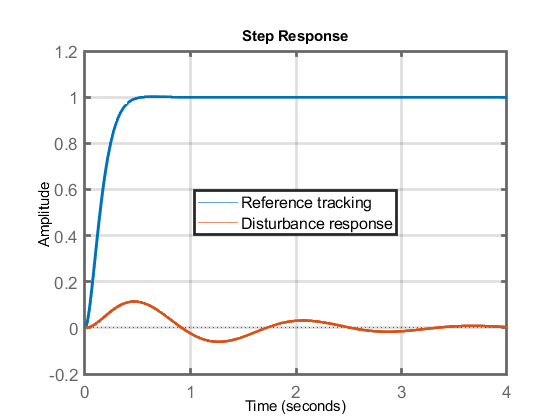


% Visualisierung
h=gca; h.LineWidth = 2; h.FontSize =13;
h.Children(1).Children(2).LineWidth =2;
h.Children(2).Children(2).LineWidth =2;
hleg = legend('Reference tracking','Disturbance response');
hleg.Location = 'best';

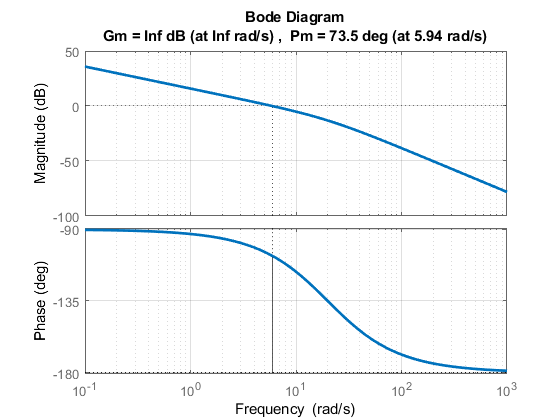

figure(9);
margin(G*R); grid on;
h=gcf;
lines = findobj(h.Children(2),'Type','Line'); set(lines,'Linewidth',2);
lines = findobj(h.Children(3),'Type','Line'); set(lines,'Linewidth',2);